# Model Comparison with BIC

This tutorial demonstrates how to compare different models using the Bayesian Information Criterion (BIC). Using a simple simulation where we know the true model underlying the data, we can compare multiple models and determine the relative evidence in favor of each.

## Data Generation 

Here we are going to generate data y that is the sum of x1, the interaction between x1 and x2, and some noise

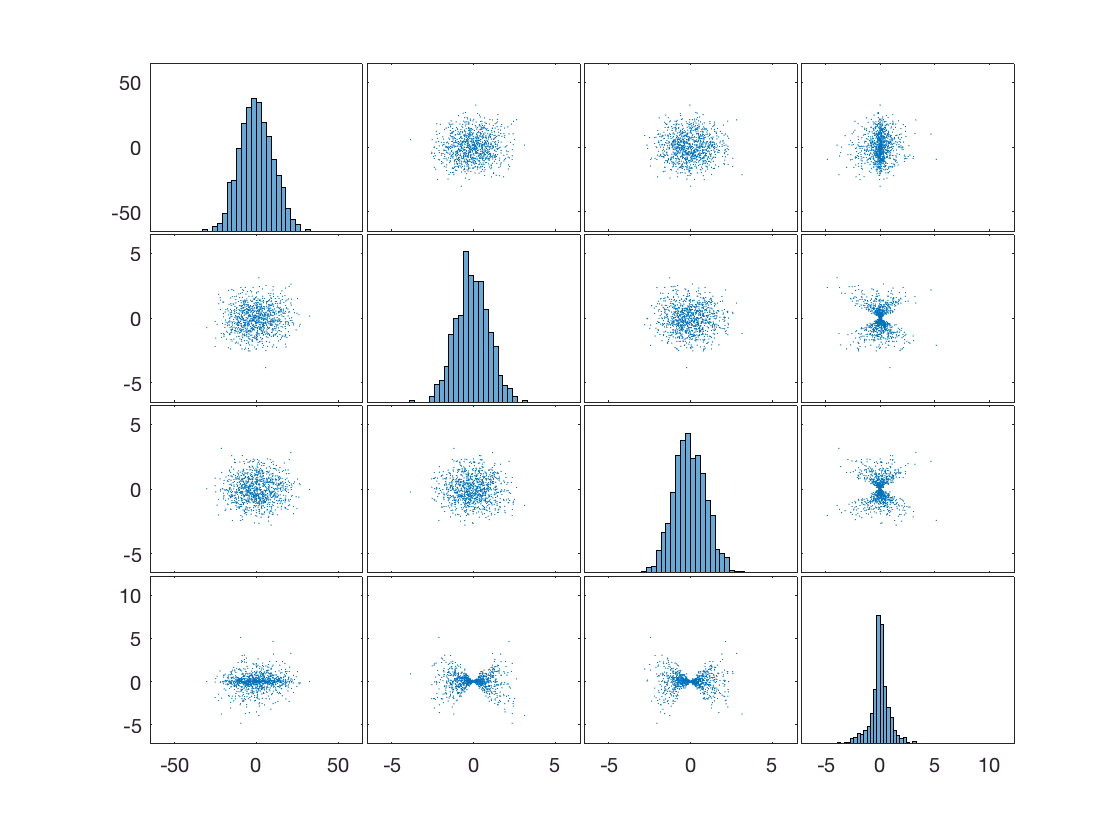

% first pick a random seed for reproducability
seed=randseed(1);
rng(seed);

% set parameter values and generate data
% we'll create a simple simulation where the true effects are an effect of x1 and 
% interaction between x1 and x2 on y, plus noise
n = 100;
noise_scale_factor = 5; %some interesting values to try here include 3, 6, and 15
x1 = randn(n,1);
x2 = randn(n,1);
y = x1  + x1.*x2 + noise_scale_factor * randn(n,1);

%plot data
plotmatrix([y x1 x2 x1.*x2])

## Model Specification

Here we are creating a set of nested models including a constant term, x1, x2, and their interaction

% constant model
X0 = ones(n,1);

% model only including x1
X1 = [X0 x1];

% model only including x2
X2 = [X0 x2];

% model including both x1 and x2
X3 = [X0 x1 x2];

% model including just the interaction
X4 = [X0 x1.*x2];

% model including x1 and the interaction of x1 and x2
X5 = [X0 x1 x1.*x2];

% model including x1 and the interaction of x1 and x2
X6 = [X0 x2 x1.*x2];

% model including x1, x2 and their interaction
X7 = [X0 x1 x2 x1.*x2];


## Fit GLMs

We can use fitglm to create GeneralizedLinearModel objects, which will also allow us to easily compute BIC

% constant model
GLM0 = fitglm(X0,y,'Intercept',false);  % Intercept is false in all models because we've added the intercept manually

% model only including x1
GLM1 = fitglm(X1,y,'Intercept',false);

% model only including x2
GLM2 = fitglm(X2,y,'Intercept',false);

% model including both x1 and x2
GLM3 = fitglm(X3,y,'Intercept',false);

% model including just the interaction
GLM4 = fitglm(X4,y,'Intercept',false);

% model including x1 and the interaction of x1 and x2
GLM5 = fitglm(X5,y,'Intercept',false);

% model including x2 and the interaction of x1 and x2
GLM6 = fitglm(X6,y,'Intercept',false);

% model including x1, x2 and their interaction
GLM7 = fitglm(X7,y,'Intercept',false);


## BIC notes

- Lower is better for all information criteria

- Likelihood is likelihood of data related to product of probabilities of observations given model. For model M and data D

- L(M | D) = L(M) * L(D | M) / L(D) .  Likelihood below is L(D | M)

- Assuming normal IID errors, maximum likelihood solution for mean of n data points is N(mean-hat, var-hat). Likelihood is proportional to MSE.

- Both BIC and AIC penalize number of free parameters (k), but BIC adusts the k penalty as a function of sample size. AIC does not.

- AIC minimizes mean squared error, and is good for prediction. But AIC favors more complex models as sample size (n) grows

- BIC is consistent, meaning that it converges on the model (if part of model test set) as n goes to infinity.  https://en.wikipedia.org/wiki/Consistent_estimator

## Compute BIC for each model

Eq 1: BIC = -2$ln\left(\hat{L} \right)$ + $k\ln \left(n\right)$, where 

$\hat{L}$ is the maximized value of the likelihood function

*k *is the number of free parameters in the model

*n *is the number of data points

This is also known as the [Swarz Criterion](http://projecteuclid.org/download/pdf_1/euclid.aos/1176344136)

See GeneralizedLinearModel.ModelCriterion

References:

Schwarz, G. (1978). Estimating the dimension of a model. *The annals of statistics*, *6*(2), 461-464.

% constant model
BIC0 = GLM0.ModelCriterion.BIC;

% model only including x1
BIC1 = GLM1.ModelCriterion.BIC;

% model only including x2
BIC2 = GLM2.ModelCriterion.BIC;

% model including both x1 and x2
BIC3 = GLM3.ModelCriterion.BIC;

% model including just the interaction
BIC4 = GLM4.ModelCriterion.BIC;

% model including x1 and the interaction of x1 and x2
BIC5 = GLM5.ModelCriterion.BIC;

% model including x1 and the interaction of x1 and x2
BIC6 = GLM6.ModelCriterion.BIC;

% model including x1, x2 and their interaction
BIC7 = GLM7.ModelCriterion.BIC;


## Compute $\Delta$BIC, wBIC, and Bayes Factors

From the raw BIC values, we can compute their relative differences ($\Delta$BIC) and transform them to reflect relative model likelihoods (wBIC), all of which can be used to approximate [Bayes Factors](http://xyala.cap.ed.ac.uk/teaching/tutorials/phylogenetics/Bayesian_Workshop/PDFs/Kass%20and%20Raftery%201995.pdf) (BF)

Formulae for computing thse values and an example of using this method can be found [here](https://www.researchgate.net/profile/Simon_Farrell/publication/8588301_AIC_model_selection_using_Akaike_weights/links/53fc51540cf22f21c2f3c376.pdf)

Eq 2: $\Delta {\text{BIC}}_i ={\text{BIC}}_i −\min \text{ }\left(\text{BIC}\right)$ 

Eq 3: $w_i BIC=$$\frac{e^{−\frac{1}{2}\Delta_i \text{BIC}} }{{\sum_{k=1}^K e}^{−\frac{1}{2}\Delta_k BIC} }$  

Eq 4: $B_{10} =\text{ }$$e^{−\frac{1}{2}\left({\text{BIC}}_1 −{\text{BIC}}_0 \right)}$ = $\frac{w_1 \text{BIC}}{w_0 \text{BIC}}$

Here, W1 and Wo are any two models.  B10 is estimated Bayes' Factor for Model 1 compared to Model 0. Higher values favor Model 1

References:

Kass, R. E., & Raftery, A. E. (1995). Bayes factors. *Journal of the american statistical association*, *90*(430), 773-795.

Wagenmakers, E. J., & Farrell, S. (2004). AIC model selection using Akaike weights. *Psychonomic bulletin & review*, *11*(1), 192-196.

- This paper claims that exp(-1/2 BIC-BIC0) is a simple approximation of the Bayes Factor comparing models.

% model names
model={'Constant' 'x1' 'x2' 'x1 + x2' 'x1 * x2' 'x1 + x1 * x2' 'x2 + x1 * x2' 'x1 + x2 + x1 * x2'}';

% make single variable with all BIC values
BIC= [BIC0 BIC1 BIC2 BIC3 BIC4 BIC5 BIC6 BIC7]';

% here we find the model with the lowest BIC and compute the difference in BIC
dBIC = BIC-min(BIC);

% compute BIC weights
% Estimated probability of model given data and set of models compared (?)
% Relative evidence for each model given full set of models evaluated
% Sums to 1 across all models.
% Can calculate Bayes Factors as ratios of these, 
% e.g., wBIC(6) ./ wBIC(1) is BF for model 6 vs. 1

wBIC = exp(-.5*dBIC)/sum(exp(-.5*dBIC));

% convert to Bayes Factors of this model vs. this model
% Higher values mean that best model is better than the target model
B = exp(.5*dBIC); % or 1 ./ exp(-.5*dBIC)

% display results in table
tbl=table(model,BIC,dBIC,wBIC,B);
display(tbl)

tbl =            model            BIC       dBIC        wBIC         B   
    ___________________    ______    _______    _________    ______

    'Constant'             7443.6    0.24726      0.28113    1.1316
    'x1'                   7445.3      1.982      0.11809     2.694
    'x2'                   7450.5     7.1542    0.0088935     35.77
    'x1 + x2'              7452.2     8.8889    0.0037359    85.153
    'x1 * x2'              7443.3          0      0.31812         1
    'x1 + x1 * x2'         7443.8    0.46619      0.25198    1.2625
    'x2 + x1 * x2'         7450.2     6.9076     0.010061    31.621
    'x1 + x2 + x1 * x2'    7450.7     7.3676    0.0079934    39.798


% True model is Model 6, x1 + x1*x2.  
% note that ratios of wBIC values are equivalent to approximations of the Bayes Factor

## Interpreting Bayes Factors and $\Delta$BIC

Kass and Raftery 1995 provides the following rule of thumb for interpretation: